# Tennis 🎾

### Import data

% URL of the dataset
url = 'https://raw.githubusercontent.com/JeffSackmann/tennis_atp/refs/heads/master/atp_matches_2024.csv';

% Read the CSV file directly from the URL
opts = detectImportOptions(url);
opts = setvartype(opts,"tourney_date","string");
T = readtable(url, opts);

% Convert 'tourney_date' to datetime format
T.date = datetime(T.tourney_date, 'InputFormat', 'yyyyMMdd');

% Select only the relevant columns
cols = {'date', 'tourney_name', 'surface', ...
        'winner_name', 'loser_name', 'winner_rank', 'loser_rank'};
T = T(:, cols)

T = 3076x7 table
       date        tourney_name    surface         winner_name               loser_name           winner_rank    loser_rank
    ___________    ____________    ________    ___________________    ________________________    ___________    __________

    01-Jan-2024    {'Brisbane'}    {'Hard'}    {'Grigor Dimitrov'}    {'Holger Rune'         }         14             8    
    01-Jan-2024    {'Brisbane'}    {'Hard'}    {'Holger Rune'    }    {'Roman Safiullin'     }          8            39    
    01-Jan-2024    {'Brisbane'}    {'Hard'}    {'Grigor Dimitrov'}    {'Jordan Thompson'     }         14            55    
    01-Jan-2024    {'Brisbane'}    {'Hard'}    {'Holger Rune'    }    {'James Duckworth'     }          8           116    


### Some metrics

% Count the number of times each player appears as the winner
wins = groupcounts(T, 'winner_name')

wins = 307x3 table
              winner_name              GroupCount    Percent 
    _______________________________    __________    ________

    {'Adam Walton'                }         3        0.097529
    {'Adria Soriano Barrera'      }         1         0.03251
    {'Adrian Mannarino'           }        16         0.52016
    {'Alan Fernando Rubio Fierros'}         1         0.03251
    {'Albert Ramos'               }         3        0.097529
    {'Alejandro Davidovich Fokina'}        19         0.61769
    {'Alejandro Moro Canas'       }         1         0.03251
    {'Alejandro Tabilo'           }        33          1.0728
    {'Aleksandar Kovacevic'       }        10          0.3251
    {'Aleksandar Vukic'           }        22         0.71521
    {'Aleksandre Bakshi'          }         2         0.06502
    {'Alex Bolt'                  }         3        0.097529
    {'Alex

[`pivot`](https://www.mathworks.com/help/matlab/ref/pivot.html) automatically counts the rows in each `(winner_name, surface)` group and spreads the result into a wide table—so the surfaces become columns and players remain rows—without any extra fill-in work

surface_stats = pivot(T, Rows="winner_name", Columns="surface", Method="count");
surface_stats = sortrows(surface_stats, "Clay", "descend")

surface_stats = 307x4 table
            winner_name            Clay    Grass    Hard
    ___________________________    ____    _____    ____

    {'Sebastian Baez'         }     26       0        5 
    {'Casper Ruud'            }     25       1       26 
    {'Alexander Zverev'       }     23       6       40 
    {'Stefanos Tsitsipas'     }     22       2       21 
    {'Francisco Cerundolo'    }     21       0       14 
    {'Luciano Darderi'        }     21       2        2 
    {'Felix Auger Aliassime'  }     18       0       15 
    {'Tomas Martin Etcheverry'}     18       1       12 
    {'Carlos Alcaraz'         }     17       8       29 
    {'Jan Lennard Struff'     }     16       6        9 
    {'Novak Djokovic'         }     16       6       16 
    {'Facundo Diaz Acosta'    }     15       0        1 
    {'Mariano Navone'         }     1

% Define player names
players = {'Novak Djokovic', 'Carlos Alcaraz'};

% Apply the filter
djoko_vs_alcaraz = T( ...
    ismember(T.winner_name, players) & ...
    ismember(T.loser_name, players), :)

djoko_vs_alcaraz = 2x7 table
       date           tourney_name        surface        winner_name            loser_name        winner_rank    loser_rank
    ___________    __________________    _________    __________________    __________________    ___________    __________

    01-Jul-2024    {'Wimbledon'     }    {'Grass'}    {'Carlos Alcaraz'}    {'Novak Djokovic'}         3             2     
    29-Jul-2024    {'Paris Olympics'}    {'Clay' }    {'Novak Djokovic'}    {'Carlos Alcaraz'}         2             3     


- `ismember(T.winner_name, players)` checks if the winner is one of the two players.

- `ismember(T.loser_name, players)` checks the same for the loser.

- The `&` combines the two conditions.

- The final `, :` selects all columns for the rows that match.

### Elo

dataset = buildDatasetElo(T)

dataset = 6152x3 table
    elo_diff    surf_elo_diff    label
    ________    _____________    _____

           0             0         1  
           0             0         0  
         -16           -16         1  
          16            16         0  
          16            16         1  
         -16           -16         0  
     0.73631       0.73631         1  
    -0.73631      -0.73631         0  
     -16.736       -16.736         1  
      16.736        16.736         0  
     -15.264       -15.264         1  
      15.264        15.264         0  
      31.264        31.264         1  
     -31.264       -31.264         0  
      16.702        16.702         1  
     -16.702       -16.702         0  


### Decision tree

%% --- 1.  Feature matrix and labels ------------------------------------
% dataset is the table returned by buildDatasetElo
X = dataset(:, {'elo_diff','surf_elo_diff'});   % two numeric predictors
y = categorical(dataset.label);                 % 0 / 1 → categorical

%% --- 2.  Train / test split (stratified 25 % hold-out) -----------------
cvp      = cvpartition(y, 'Holdout', 0.25);     % stratifies automatically
Xtrain   = X(cvp.training, :);
ytrain   = y(cvp.training);
Xtest    = X(cvp.test, :);
ytest    = y(cvp.test);

%% --- 3.  Fit a shallow decision tree ----------------------------------
% “max_depth = 4” in scikit-learn ≈ (2^4−1) = 15 terminal nodes max.
tree = fitctree(Xtrain, ytrain, ...
                'MaxNumSplits', 15, ...        % controls depth
                'SplitCriterion', 'gdi', ...
                'PredictorNames', {'elo_diff','surf_elo_diff'}, ...
                'ClassNames', categories(ytrain));

%% --- 4.  Predictions, accuracy, AUC -----------------------------------
[predsCell, scores] = predict(tree, Xtest);         % scores(:,2) = P(label==1)
preds   = categorical(predsCell, categories(ytest));

accuracy = mean(preds == ytest);

[~,~,~,auc] = perfcurve(double(ytest), scores(:,2), '1');

fprintf('Decision-Tree accuracy : %.3f\n', accuracy);

Decision-Tree accuracy : 0.573


fprintf('Decision-Tree AUC      : %.3f\n', auc);

Decision-Tree AUC      : 0.376


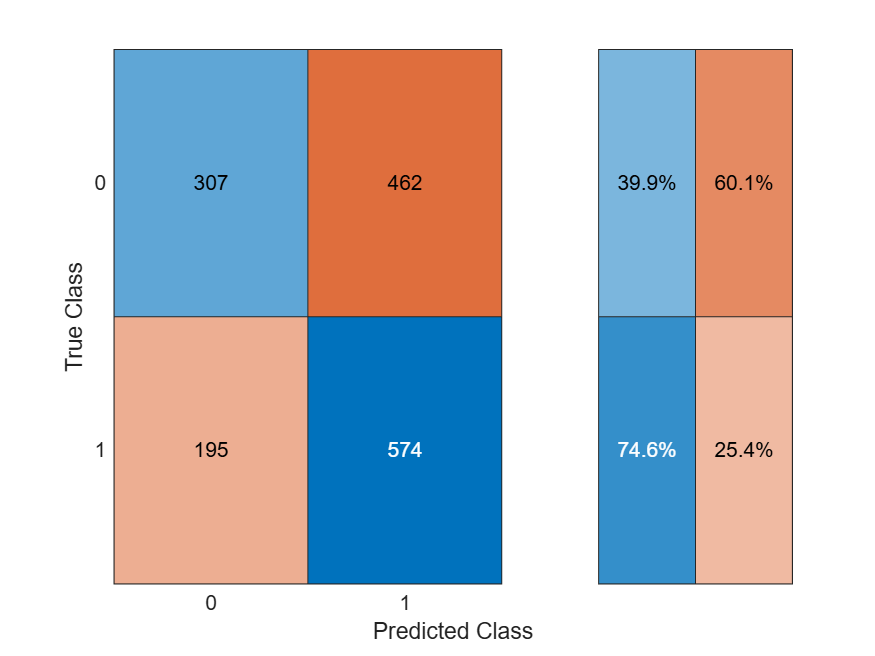


%% --- 5.  (Optional) quick visuals -------------------------------------
% Confusion matrix
confusionchart(ytest, preds, 'RowSummary','row-normalized')

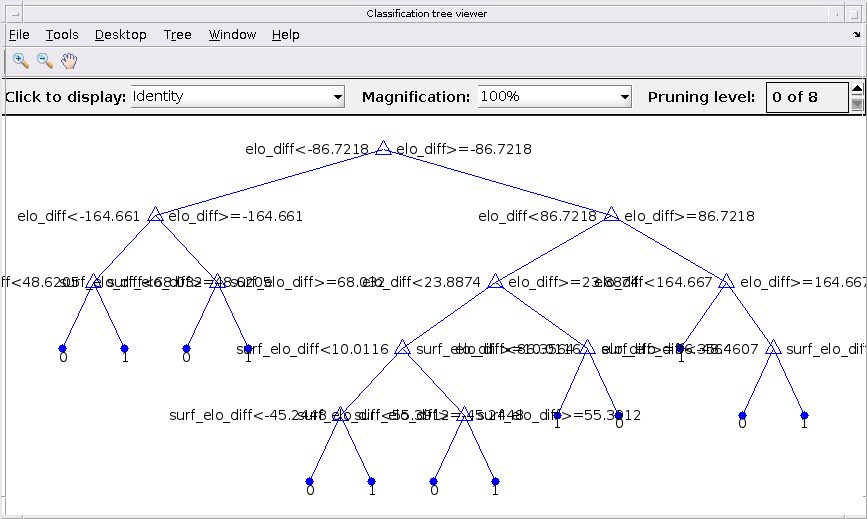


% Inspect the learned tree
view(tree, 'Mode', 'graph')

### Random Forest

%% --- Random Forest (200 trees, depth ≤ 5) -----------------------------
rng(42)                                   % for reproducibility

maxDepth     = 5;
maxNumSplits = 2^maxDepth - 1;            % 31 → depth-5 tree

tTree  = templateTree('MaxNumSplits', maxNumSplits);

forest = fitcensemble( Xtrain, ytrain, ...
                       'Method',            'Bag', ...    % bagging = RF
                       'NumLearningCycles', 200, ...
                       'Learners',          tTree, ...
                       'ClassNames',        categories(ytrain) );

%% --- Predictions & metrics --------------------------------------------
[predsCell, scores] = predict(forest, Xtest);
preds = categorical(predsCell, categories(ytest));  % same type as ytest

accuracy = mean(preds == ytest);

[~,~,~,auc] = perfcurve(double(ytest), scores(:,2), 1);

fprintf('Random-Forest accuracy : %.3f\n', accuracy);

Random-Forest accuracy : 0.594


fprintf('Random-Forest AUC      : %.3f\n', auc);

Random-Forest AUC      : 0.361



%% Confusion matrix
confusionchart(ytest, preds, 'RowSummary','row-normalized');

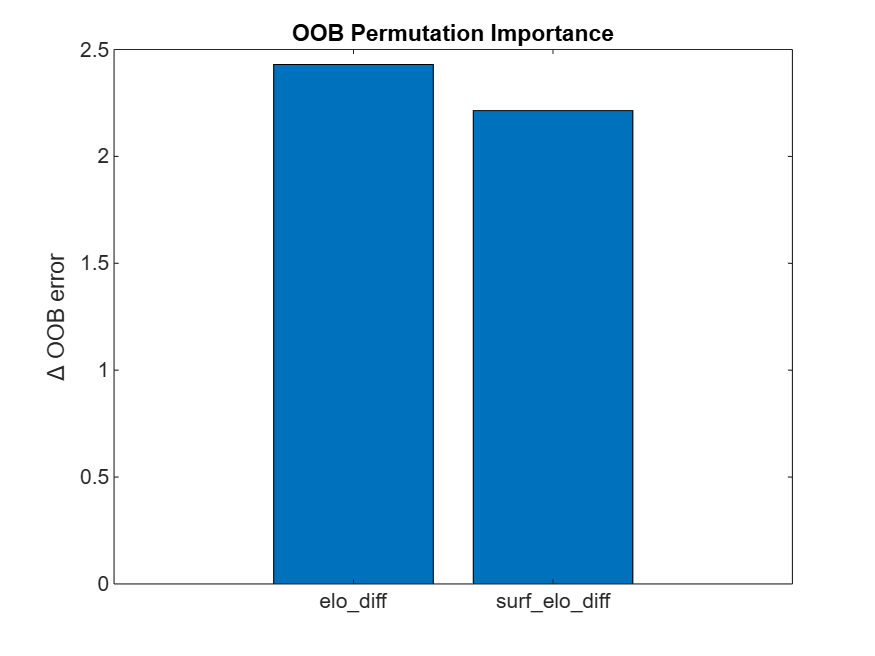

%% Feature importance (OOB permutation)
imp = oobPermutedPredictorImportance(forest); % function call

figure
bar(imp)
xticklabels({'elo\_diff','surf\_elo\_diff'})
title('OOB Permutation Importance')
ylabel('Δ OOB error')

### Gradient Boosting

%% --- Gradient Boosting (LogitBoost, depth-3 stumps) -------------------
rng(42)                                   % for reproducibility

maxDepth      = 3;                        % scikit default
maxNumSplits  = 2^maxDepth - 1;           % 7
nTrees        = 100;                      % scikit default (can tune)

tTree   = templateTree('MaxNumSplits', maxNumSplits);   % weak learner
gbm    = fitcensemble( Xtrain, ytrain, ...
                       'Method',            'LogitBoost', ...
                       'NumLearningCycles', nTrees, ...
                       'Learners',          tTree, ...
                       'ClassNames',        categories(ytrain), ...
                       'LearnRate',         0.1 );      % scikit default

%% --- Predictions & metrics --------------------------------------------
[predsCell, scores] = predict(gbm, Xtest);
preds   = categorical(predsCell, categories(ytest));

accuracy = mean(preds == ytest);

[~,~,~,auc] = perfcurve(double(ytest), scores(:,2), 1);

fprintf('Gradient-Boosting accuracy : %.3f\n', accuracy);

Gradient-Boosting accuracy : 0.590


fprintf('Gradient-Boosting AUC      : %.3f\n', auc);

Gradient-Boosting AUC      : 0.360


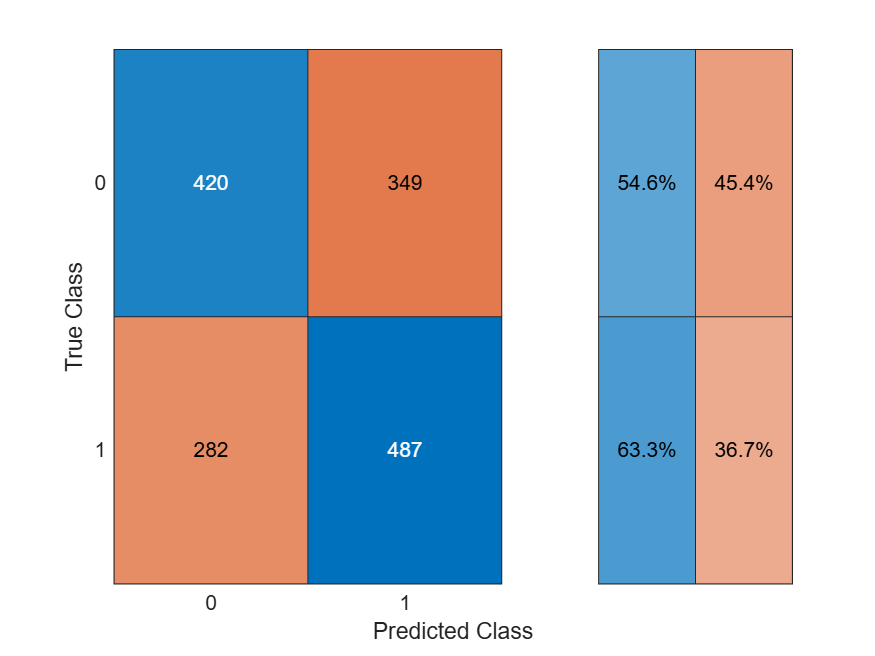


%% Confusion matrix
confusionchart(ytest, preds, 'RowSummary','row-normalized');

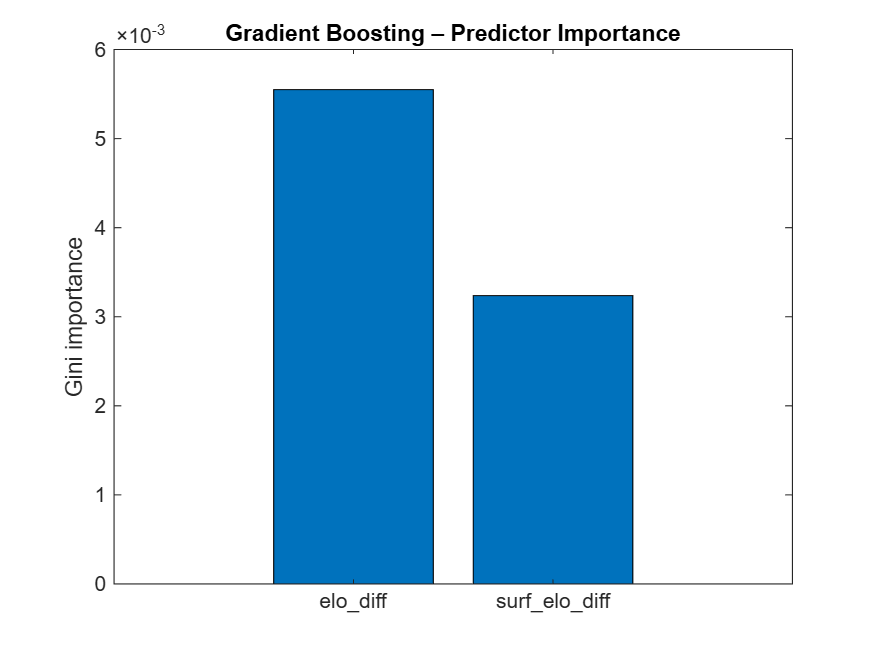

%% (Optional) feature importance ----------------------------------------
imp = predictorImportance(gbm);   % Gini importance for boosted trees

figure
bar(imp)
xticklabels({'elo\_diff','surf\_elo\_diff'})
title('Gradient Boosting – Predictor Importance')
ylabel('Gini importance')

### Utils

function [dataset, eloMap, surfEloMap] = buildDatasetElo(T)
%BUILD DATASET WITH GLOBAL- AND SURFACE-ELO DIFFERENCES
%   T – table with at least the columns:
%        'tourney_date' (numeric or datetime), 'winner_name', 'loser_name', 'surface'
%
%   dataset     – table of two features + binary label (one row per player-perspective)
%   eloMap      – containers.Map keyed by player name → final global Elo
%   surfEloMap  – containers.Map keyed by "player_surface" → final surface-specific Elo

% sort chronologically (MATLAB datetime or yyyymmdd numeric both work)
T   = sortrows(T, 'date');

K           = 32;            % Elo K-factor
baseRating  = 1500.0;        % default starting Elo
eloMap      = containers.Map('KeyType', 'char', 'ValueType', 'double');
surfEloMap  = containers.Map('KeyType', 'char', 'ValueType', 'double');

% we’ll grow a cell array then convert to table (simplest/clear)
rows = {};  
for i = 1:height(T)
    w       = T.winner_name{i};
    l       = T.loser_name{i};
    surface = T.surface{i};

    % ----- fetch (or lazily create) ratings -----
    if ~isKey(eloMap, w), eloMap(w) = baseRating; end
    if ~isKey(eloMap, l), eloMap(l) = baseRating; end
    keyWS = [w '_' surface];
    keyLS = [l '_' surface];
    if ~isKey(surfEloMap, keyWS), surfEloMap(keyWS) = baseRating; end
    if ~isKey(surfEloMap, keyLS), surfEloMap(keyLS) = baseRating; end

    eloW   = eloMap(w);
    eloL   = eloMap(l);
    surfW  = surfEloMap(keyWS);
    surfL  = surfEloMap(keyLS);

    % ----- add two perspectives -----
    rows(end+1,1:3) = {eloW - eloL,  surfW - surfL, 1}; %#ok<AGROW>
    rows(end+1,1:3) = {eloL - eloW,  surfL - surfW, 0}; %#ok<AGROW>

    % ----- update global Elo -----
    expW  = 1 / (1 + 10^((eloL - eloW)/400));
    eloMap(w) = eloW + K * (1 - expW);
    eloMap(l) = eloL + K * (0 - (1 - expW));

    % ----- update surface-specific Elo -----
    expWS = 1 / (1 + 10^((surfL - surfW)/400));
    surfEloMap(keyWS) = surfW + K * (1 - expWS);
    surfEloMap(keyLS) = surfL + K * (0 - (1 - expWS));
end

dataset = cell2table(rows, 'VariableNames', {'elo_diff','surf_elo_diff','label'});
end

export tennis.mlx tennis.md;